%% 16-Channel Epoch Extraction and SVM Classification
% This Live Script:
%
% 1. Loads raw EEG files from 10 subjects and 3 imagery runs
% 2. Selects 16 channels around the motor cortex
% 3. Filters the EEG from 8 to 30 Hz
% 4. Extracts Left, Right and Rest epochs
% 5. Combines epochs from all files
% 6. Extracts mu and beta bandpower features
% 7. Trains a linear multiclass SVM
% 8. Calculates classification accuracy

clear;
close all;
clc;


%% Step 1: Set the project path

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';


%% Step 2: Define subjects and runs

subjects = {'S001','S002','S003','S004','S005', ...
            'S006','S007','S008','S009','S010'};

% Motor imagery runs
runs = {'R04','R08','R12'};


%% Step 3: Select 16 motor-related EEG channels

% Premotor channels:
% FC3, FC1, FCz, FC2, FC4
%
% Motor cortex channels:
% C5, C3, C1, Cz, C2, C4, C6
%
% Somatosensory channels:
% CP3, CP1, CP2, CP4

selectedChannels = ["FC3", "FC1", "FCz", "FC2", "FC4", ...
                    "C5",  "C3",  "C1",  "Cz",  "C2", ...
                    "C4",  "C6", ...
                    "CP3", "CP1", "CP2", "CP4"];

disp('Requested 16 motor-related channels:');

Requested 16 motor-related channels:


disp(selectedChannels');

    "FC3"
    "FC1"
    "FCz"
    "FC2"
    "FC4"
    "C5"
    "C3"
    "C1"
    "Cz"
    "C2"
    "C4"
    "C6"
    "CP3"
    "CP1"
    "CP2"
    "CP4"





%% Step 4: Define the epoch time window

% Extract EEG from 0 to 4 seconds after each event marker.

tmin = 0;
tmax = 4;


%% Step 5: Initialize epoch storage

all_left = [];
all_right = [];
all_rest = [];

actualChannelLabels = strings(1,16);

fileCount = 0;


%% Step 6: Process all subjects and runs

for s = 1:length(subjects)

    for r = 1:length(runs)

        %% Create the EDF filename

        filename = fullfile(basePath, 'Data', ...
            [subjects{s}, runs{r}, '.edf']);

        fprintf('\nProcessing: %s%s\n', ...
            subjects{s}, runs{r});


        %% Load raw EEG

        EEG = pop_biosig(filename);

        fprintf('Original channels: %d\n', EEG.nbchan);


        %% Find the 16 channels

        % PhysioNet may store channel names with dots.
        %
        % Example:
        % C3 may appear as C3..
        %
        % We temporarily remove the dots before matching.

        eegChannelLabels = string({EEG.chanlocs.labels});

        cleanEEGLabels = upper(regexprep( ...
            eegChannelLabels, '[^A-Za-z0-9]', ''));

        cleanSelectedLabels = upper(selectedChannels);

        [channelsFound, channelIndices] = ...
            ismember(cleanSelectedLabels, cleanEEGLabels);


        %% Check whether every channel exists

        if any(~channelsFound)

            missingChannels = ...
                selectedChannels(~channelsFound);

            error('Channels missing in %s%s: %s', ...
                subjects{s}, ...
                runs{r}, ...
                strjoin(missingChannels, ', '));

        end


        %% Keep only the selected 16 channels

        EEG = pop_select(EEG, ...
            'channel', channelIndices);

        EEG = eeg_checkset(EEG);

        fprintf('Selected channels: %d\n', EEG.nbchan);


        %% Save the actual channel order

        if fileCount == 0

            actualChannelLabels = ...
                string({EEG.chanlocs.labels});

            disp('Actual channel order used:');
            disp(actualChannelLabels');

        end


        %% Apply 8–30 Hz band-pass filter

        EEG = pop_eegfiltnew(EEG, 8, 30);

        EEG = eeg_checkset(EEG);


        %% Extract Left-fist motor imagery epochs

        % T1 = imagined left-fist movement

        EEG_left = pop_epoch( ...
            EEG, ...
            {'T1'}, ...
            [tmin tmax], ...
            'epochinfo', 'yes');


        %% Extract Right-fist motor imagery epochs

        % T2 = imagined right-fist movement

        EEG_right = pop_epoch( ...
            EEG, ...
            {'T2'}, ...
            [tmin tmax], ...
            'epochinfo', 'yes');


        %% Extract Rest epochs

        % T0 = rest

        EEG_rest = pop_epoch( ...
            EEG, ...
            {'T0'}, ...
            [tmin tmax], ...
            'epochinfo', 'yes');


        %% Display epochs in the current file

        fprintf('Left epochs:  %d\n', EEG_left.trials);
        fprintf('Right epochs: %d\n', EEG_right.trials);
        fprintf('Rest epochs:  %d\n', EEG_rest.trials);


        %% Combine epochs

        % EEG data shape:
        %
        % channels × time points × epochs

        all_left = cat(3, ...
            all_left, EEG_left.data);

        all_right = cat(3, ...
            all_right, EEG_right.data);

        all_rest = cat(3, ...
            all_rest, EEG_rest.data);


        fileCount = fileCount + 1;

        fprintf('Completed file %d of 30\n', fileCount);

    end

end


Processing: S001R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


Actual channel order used:


    "Fc3."
    "Fc1."
    "Fcz."
    "Fc2."
    "Fc4."
    "C5.."
    "C3.."
    "C1.."
    "Cz.."
    "C2.."
    "C4.."
    "C6.."
    "Cp3."
    "Cp1."
    "Cp2."
    "Cp4."



pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 1 of 30



Processing: S001R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 2 of 30



Processing: S001R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 3 of 30



Processing: S002R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 4 of 30



Processing: S002R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 5 of 30



Processing: S002R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 6 of 30



Processing: S003R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 7 of 30



Processing: S003R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 8 of 30



Processing: S003R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 9 of 30



Processing: S004R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 10 of 30



Processing: S004R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 11 of 30



Processing: S004R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 12 of 30



Processing: S005R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 13 of 30



Processing: S005R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 14 of 30



Processing: S005R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 15 of 30



Processing: S006R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 16 of 30



Processing: S006R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 17 of 30



Processing: S006R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 18 of 30



Processing: S007R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 19 of 30



Processing: S007R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 20 of 30



Processing: S007R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 21 of 30



Processing: S008R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 22 of 30



Processing: S008R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  7


Right epochs: 8


Rest epochs:  14


Completed file 23 of 30



Processing: S008R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 24 of 30



Processing: S009R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 25 of 30



Processing: S009R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 26 of 30



Processing: S009R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 27 of 30



Processing: S010R04


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 28 of 30



Processing: S010R08


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 29 of 30



Processing: S010R12


sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


Original channels: 64


Removing 48 channel(s)...


Selected channels: 16


pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
pop_epoch(): checking epochs for data discontinuity


Left epochs:  8


Right epochs: 7


Rest epochs:  14


Completed file 30 of 30




%% Step 7: Display combined epoch data

samplingRate = EEG.srate;

disp(' ');

disp('======================================');

disp('Combined 16-Channel Epoch Dataset');

Combined 16-Channel Epoch Dataset


disp('======================================');


disp(['Files processed: ', ...
    num2str(fileCount)]);

Files processed: 30



disp(['Sampling rate: ', ...
    num2str(samplingRate), ' Hz']);

Sampling rate: 160 Hz



disp(['Left data shape:  ', ...
    mat2str(size(all_left))]);

Left data shape:  [16 640 230]



disp(['Right data shape: ', ...
    mat2str(size(all_right))]);

Right data shape: [16 640 220]



disp(['Rest data shape:  ', ...
    mat2str(size(all_rest))]);

Rest data shape:  [16 640 420]



disp(['Total left epochs:  ', ...
    num2str(size(all_left,3))]);

Total left epochs:  230



disp(['Total right epochs: ', ...
    num2str(size(all_right,3))]);

Total right epochs: 220



disp(['Total rest epochs:  ', ...
    num2str(size(all_rest,3))]);

Total rest epochs:  420




%% Step 8: Save the combined 16-channel epochs

epochOutputFile = fullfile(basePath, ...
    'Outputs', ...
    'Filtered data', ...
    'combined_epochs_16channels.mat');

save(epochOutputFile, ...
    'all_left', ...
    'all_right', ...
    'all_rest', ...
    'selectedChannels', ...
    'actualChannelLabels', ...
    'samplingRate', ...
    'tmin', ...
    'tmax', ...
    'subjects', ...
    'runs', ...
    '-v7.3');

disp('16-channel epoch data saved successfully.');

16-channel epoch data saved successfully.




%% Step 9: Balance the three classes

% Find the smallest class size.

numberOfEpochs = min([size(all_left,3), ...
                      size(all_right,3), ...
                      size(all_rest,3)]);

fprintf('\nBalanced epochs per class: %d\n', ...
    numberOfEpochs);


Balanced epochs per class: 220



% Use the same random selection every time.

rng(42);

leftEpochIndices = randperm( ...
    size(all_left,3), numberOfEpochs);

rightEpochIndices = randperm( ...
    size(all_right,3), numberOfEpochs);

restEpochIndices = randperm( ...
    size(all_rest,3), numberOfEpochs);

leftData = all_left(:,:,leftEpochIndices);

rightData = all_right(:,:,rightEpochIndices);

restData = all_rest(:,:,restEpochIndices);


%% Step 10: Extract mu and beta features

% Each channel produces:
%
% 1 mu-band feature
% 1 beta-band feature
%
% 16 channels × 2 frequency bands = 32 features

leftFeatures = extract_motor_bandpower( ...
    leftData, samplingRate);

rightFeatures = extract_motor_bandpower( ...
    rightData, samplingRate);

restFeatures = extract_motor_bandpower( ...
    restData, samplingRate);

disp(' ');

disp('=== Extracted Feature Shapes ===');

=== Extracted Feature Shapes ===



disp(['Left features:  ', ...
    mat2str(size(leftFeatures))]);

Left features:  [220 32]



disp(['Right features: ', ...
    mat2str(size(rightFeatures))]);

Right features: [220 32]



disp(['Rest features:  ', ...
    mat2str(size(restFeatures))]);

Rest features:  [220 32]




%% Step 11: Create the feature names

% Remove dots from the actual PhysioNet labels.

cleanChannelNames = regexprep( ...
    actualChannelLabels, '[^A-Za-z0-9]', '');

numberOfChannels = length(cleanChannelNames);

featureNames = strings(1, numberOfChannels * 2);

for c = 1:numberOfChannels

    featureNames(2*c - 1) = ...
        cleanChannelNames(c) + "_mu";

    featureNames(2*c) = ...
        cleanChannelNames(c) + "_beta";

end

disp(' ');

disp('The 32 features used are:');

The 32 features used are:


disp(featureNames');

    "Fc3_mu"
    "Fc3_beta"
    "Fc1_mu"
    "Fc1_beta"
    "Fcz_mu"
    "Fcz_beta"
    "Fc2_mu"
    "Fc2_beta"
    "Fc4_mu"
    "Fc4_beta"
    "C5_mu"
    "C5_beta"
    "C3_mu"
    "C3_beta"
    "C1_mu"
    "C1_beta"
    "Cz_mu"
    "Cz_beta"
    "C2_mu"
    "C2_beta"
    "C4_mu"
    "C4_beta"
    "C6_mu"
    "C6_beta"
    "Cp3_mu"
    "Cp3_beta"
    "Cp1_mu"
    "Cp1_beta"
    "Cp2_mu"
    "Cp2_beta"
    "Cp4_mu"
    "Cp4_beta"





%% Step 12: Combine features and labels

X = [leftFeatures;
     rightFeatures;
     restFeatures];

Y = [repmat("LEFT", numberOfEpochs, 1);
     repmat("RIGHT", numberOfEpochs, 1);
     repmat("REST", numberOfEpochs, 1)];

Y = categorical(Y);

disp(['Final feature matrix shape: ', ...
    mat2str(size(X))]);

Final feature matrix shape: [660 32]



% Expected:
% total epochs × 32 features


%% Step 13: Split into training and testing sets

% 80% training
% 20% testing

rng(42);

cv = cvpartition(Y, ...
    'HoldOut', 0.20);

trainingIndices = training(cv);

testingIndices = test(cv);

XTrain = X(trainingIndices,:);

YTrain = Y(trainingIndices);

XTest = X(testingIndices,:);

YTest = Y(testingIndices);

disp(' ');

disp('=== Training and Testing Data ===');

=== Training and Testing Data ===



disp(['Training samples: ', ...
    num2str(size(XTrain,1))]);

Training samples: 528



disp(['Testing samples:  ', ...
    num2str(size(XTest,1))]);

Testing samples:  132




%% Step 14: Train the linear multiclass SVM

% The linear kernel is used because it is easier to understand.
%
% Standardize = true scales the features before training.

svmTemplate = templateSVM( ...
    'KernelFunction', 'linear', ...
    'Standardize', true);

svmModel16Channels = fitcecoc( ...
    XTrain, ...
    YTrain, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

disp('16-channel linear SVM trained successfully.');

16-channel linear SVM trained successfully.




%% Step 15: Test the SVM

predictedLabels = predict( ...
    svmModel16Channels, XTest);

accuracy16Channels = mean( ...
    predictedLabels == YTest) * 100;

fprintf('\n16-channel, 32-feature accuracy: %.2f%%\n', ...
    accuracy16Channels);


16-channel, 32-feature accuracy: 48.48%


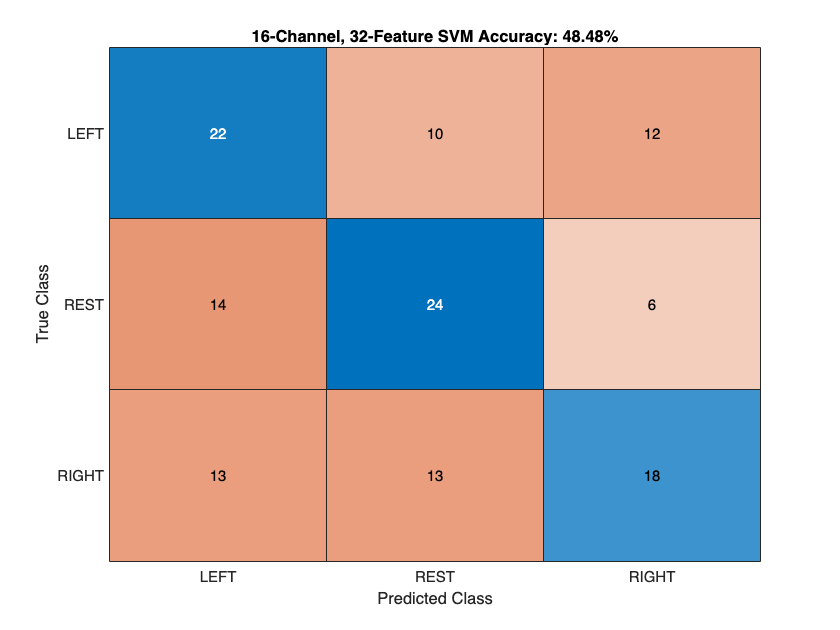



%% Step 16: Display confusion matrix

figure;

confusionchart(YTest, predictedLabels);

title(['16-Channel, 32-Feature SVM Accuracy: ', ...
    num2str(accuracy16Channels, '%.2f'), '%']);



%% Step 17: Display final model summary

disp(' ');

disp('======================================');

disp('Final 16-Channel Model Summary');

Final 16-Channel Model Summary


disp('======================================');


disp(['Number of channels: ', ...
    num2str(numberOfChannels)]);

Number of channels: 16



disp(['Number of features: ', ...
    num2str(size(X,2))]);

Number of features: 32



disp(['Training samples: ', ...
    num2str(size(XTrain,1))]);

Training samples: 528



disp(['Testing samples: ', ...
    num2str(size(XTest,1))]);

Testing samples: 132



disp(['Accuracy: ', ...
    num2str(accuracy16Channels, '%.2f'), '%']);

Accuracy: 48.48%



disp('Channels used:');

Channels used:


disp(actualChannelLabels');

    "Fc3."
    "Fc1."
    "Fcz."
    "Fc2."
    "Fc4."
    "C5.."
    "C3.."
    "C1.."
    "Cz.."
    "C2.."
    "C4.."
    "C6.."
    "Cp3."
    "Cp1."
    "Cp2."
    "Cp4."





%% Step 18: Save the SVM model

modelOutputFile = fullfile(basePath, ...
    'Outputs', ...
    'svm_16channel_32feature_model.mat');

save(modelOutputFile, ...
    'svmModel16Channels', ...
    'accuracy16Channels', ...
    'featureNames', ...
    'selectedChannels', ...
    'actualChannelLabels', ...
    'samplingRate', ...
    'XTrain', ...
    'YTrain', ...
    'XTest', ...
    'YTest');

disp('16-channel SVM model saved successfully.');

16-channel SVM model saved successfully.




%% Local Function: Extract Mu and Beta Bandpower


function features = extract_motor_bandpower(data, samplingRate)

    % Input data shape:
    %
    % channels × time points × epochs

    numberOfChannels = size(data,1);

    numberOfEpochs = size(data,3);

    % Two features per channel:
    %
    % Mu power
    % Beta power

    numberOfFeatures = numberOfChannels * 2;

    features = zeros( ...
        numberOfEpochs, numberOfFeatures);


    %% Go through every epoch

    for e = 1:numberOfEpochs

        featurePosition = 1;


        %% Go through every channel

        for c = 1:numberOfChannels

            % Select one EEG signal from one epoch.

            signal = double(data(c,:,e));


            %% Calculate power spectral density

            [powerSpectrum, frequencies] = ...
                pwelch(signal, [], [], [], samplingRate);


            %% Calculate mu-band power

            % Mu frequency range:
            % 8 to 12 Hz

            muPower = mean( ...
                powerSpectrum( ...
                frequencies >= 8 & ...
                frequencies <= 12));


            %% Calculate beta-band power

            % Beta frequency range:
            % 13 to 30 Hz

            betaPower = mean( ...
                powerSpectrum( ...
                frequencies >= 13 & ...
                frequencies <= 30));


            %% Store the features

            features(e,featurePosition) = ...
                log10(muPower + eps);

            features(e,featurePosition + 1) = ...
                log10(betaPower + eps);

            featurePosition = ...
                featurePosition + 2;

        end

    end

end